# Simulate Physical Model

## Open Model

root = 'turboShaftEngine';
modelName = 'simpleHelicopter_23b';
engineMode = 'PhysMod';
heatMode = 'Stairs';
open_system(modelName)
set_param([modelName,'/Engine'],'LabelModeActivechoice', engineMode)
set_param([modelName,'/HeatIn'],'LabelModeActivechoice', heatMode)

Enable or disable network trainning:

train = true;

## Generate Simulation Scenarios

Set the simulation stop time in (s)

simStopTime = 300;

Create different simulation scenarios by specifying the the heat input stairs

ascendScenarioVector = 2e3:0.5e3:5e3;
ascendDescentScenarioVector = [2e3:1e3:5e3 5e3:-1e3:2.5e3];
referenceHeatStates = {
                    {[ascendScenarioVector(1), ascendScenarioVector(2:end)+155],simStopTime}, ...
                    {[ascendScenarioVector(1), ascendScenarioVector(2:end)+305],simStopTime}, ...
                    {[ascendScenarioVector(1), ascendScenarioVector(2:end)+455], simStopTime}, ...
                    {[ascendScenarioVector(1), ascendScenarioVector(2:end)+455], simStopTime}, ...
                    {[ascendScenarioVector(1), ascendScenarioVector(2:end)+605],simStopTime}, ...
                    {[ascendScenarioVector(1), ascendScenarioVector(2:end)+655], simStopTime}, ...
                    {ascendDescentScenarioVector,simStopTime}, ...
                    {[ascendDescentScenarioVector(1), ascendDescentScenarioVector(2:end)+150],simStopTime}, ...                      
                    {[ascendDescentScenarioVector(1), ascendDescentScenarioVector(2:end)+300],simStopTime}, ...
                    {[ascendDescentScenarioVector(1), ascendDescentScenarioVector(2:end)+450], simStopTime}, ...
                    {[ascendDescentScenarioVector(1), ascendDescentScenarioVector(2:end)+600],simStopTime}, ...
                    {[ascendDescentScenarioVector(1), ascendDescentScenarioVector(2:end)+650], simStopTime}};

Generate the simulation scenarios and save them in MAT files

for ix=1:numel(referenceHeatStates)
    generateInputs(scenarioDir, referenceHeatStates{ix}{1},...
    referenceHeatStates{ix}{2}, ix, 'heatIn')
end

## Generate Simulink Simulation Inputs

From the generated scenarios you can create "Simulink.SimulationInputs"

load_system(modelName)
clearvars simIn
fileList = listSimInpFiles(scenarioDir);
numCases = length(fileList);
scenario = {};
simIn(1:numCases) = Simulink.SimulationInput(modelName);

for ix=1:numCases
    fileName = split(fileList{ix},'.');
    scenario{ix} = load(fileList{ix});
    aux = split(fileName{1},'_');
    scenarioSimStopTime = aux{end};
    simIn(ix) = simIn(ix).setModelParameter('StopTime', scenarioSimStopTime);
    simIn(ix) = setVariable(simIn(ix), 'Qin', scenario{ix}.stateVecRef{1}.Values.Data', ...
        'Workspace', modelName);    
    simIn(ix) = setVariable(simIn(ix),'Qin_time', scenario{ix}.stateVecRef{1}.Values.Time', ...
        'Workspace', modelName);
end

## Simulate

Simulate in parallel and save the results

out = parsim(simIn,'ShowSimulationManager','on');

[16-Feb-2024 13:54:32] Checking for availability of parallel pool...
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.
[16-Feb-2024 13:55:07] Starting Simulink on parallel workers...
[16-Feb-2024 13:55:17] Loading project on parallel workers...
[16-Feb-2024 13:55:17] Configuring simulation cache folder on parallel workers...
[16-Feb-2024 13:55:31] Loading model on parallel workers...
[16-Feb-2024 13:55:46] Running simulations...
[16-Feb-2024 13:59:04] Cleaning up parallel workers...


save(fullfile(simOutDir,'simOuts'),'out') 

# Prepare Data for Training

To achieve better performance the data are resampled, normalized.

## Resample simulation data

Extract data table from simulation results

for ix = 1:length(out)
    resultsTable{ix} = out(ix).logsout.extractTimetable;
end

Resample the data in seconds using [anonymous functions](https://uk.mathworks.com/help/matlab/matlab_prog/anonymous-functions.html) and [cellfun](https://uk.mathworks.com/help/matlab/ref/cellfun.html):

sampleTime = 0.1;
timeStep = out(1).tout(2)-out(1).tout(1);
batchDownSample = @(x) downsample(x,sampleTime/timeStep);
resampledData = cellfun(batchDownSample, resultsTable,'UniformOutput', false);

Reorder signals using [movevars](https://uk.mathworks.com/help/matlab/ref/table.movevars.html): 

commandSignals = {'Altitude (m)', 'Qin (kW)'};
resampledData = cellfun(@(x) movevars(x,commandSignals{1},'Before',1), resampledData,'UniformOutput', false);
resampledData = cellfun(@(x) movevars(x,commandSignals{2},'Before',2), resampledData,'UniformOutput', false);
resampledData = cellfun(@(x) movevars(x,'T3 (K)','After',8), resampledData,'UniformOutput', false);
resampledData = cellfun(@(x) movevars(x,'P2 (Pa)','After',8), resampledData,'UniformOutput', false);

sigNames = resampledData{1}.Properties.VariableNames;

## Visualize resampled data

Visualize table data with [stackedplot](https://uk.mathworks.com/help/matlab/ref/stackedplot.html):

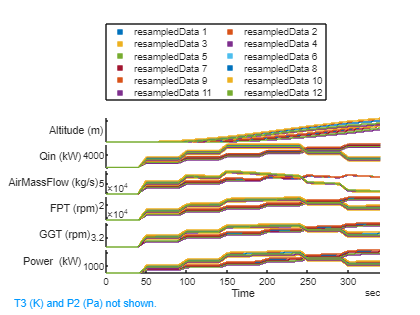

figure
stackedplot(resampledData)

## Normalize data

Concatenate the data using the [vertcat](https://uk.mathworks.com/help/matlab/ref/double.vertcat.html?searchHighlight=Vertcat&s_tid=doc_srchtitle) function:

concatDataTrain = vertcat(resampledData{:});

calculate the mean and standard deviation of the simulation data, with [mean](https://uk.mathworks.com/help/matlab/ref/mean.html) and [std](https://uk.mathworks.com/help/matlab/ref/std.html) functions

meanTrain = mean(concatDataTrain);
stdTrain = std(concatDataTrain);

save the results and clear the concatenated data

clear concatDataTrain
save(fullfile(proj.RootFolder, root,"Scripts","Initialization","meanTrain.mat"), "meanTrain")
save(fullfile(proj.RootFolder, root,"Scripts","Initialization","stdTrain.mat"), "stdTrain")

Apply gaussian normalization to the entire set of data.

normalize = @(x,mu,sigma) (x - mu) ./ sigma;
dataTrainNormComp = cellfun(@(x) normalize(x, meanTrain, stdTrain), resampledData, 'UniformOutput', false);
initValues = dataTrainNormComp{1}(1,:);
save(fullfile(proj.RootFolder, root,"Scripts","Initialization","initValues.mat"), "initValues")

## Prepare data for training

Define the normalized inputs and the expected responses as seen below:

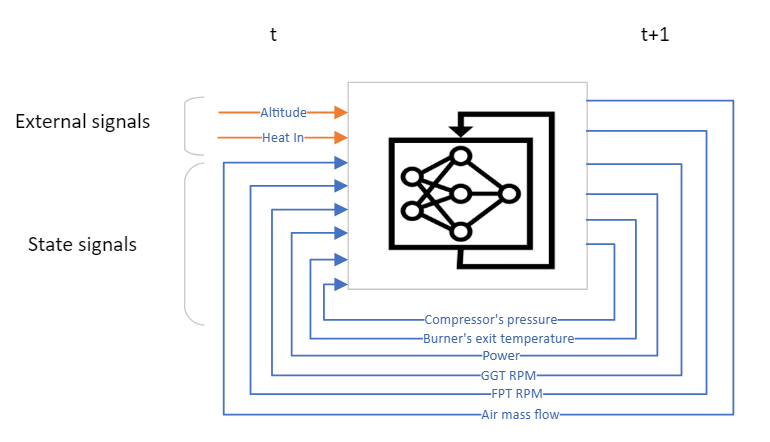

outStartIdx = length(commandSignals)+1;
inOut = @(x)[{x(1:end-1,:)} {x(2:end, outStartIdx:end)}];

aux = cellfun(inOut,dataTrainNormComp,'UniformOutput', false);

for ix=1:numel(dataTrainNormComp)
    inputTrain{ix} = table2array(aux{ix}{1});
    responseTrain{ix} = table2array(aux{ix}{2});
end
clear aux

# Train a Neural Network

## Define the inputs/outputs

Define the number of inputs and outputs of the neural network. Create respective datasets that correspond to the inputs and outputs of each timestep.

numFeatures = length(sigNames);
numResponses = length(sigNames)-length(commandSignals);
numHiddenUnits = 150;
dropoutProbability = 0.2;

## Network architecture

Choose [lstmLayer](https://uk.mathworks.com/help/deeplearning/ref/nnet.cnn.layer.lstmlayer.html) for timeseries prediction 

layers = [
    sequenceInputLayer(numFeatures,"Name","input")
    lstmLayer(numHiddenUnits,"Name","lstm","OutputMode","sequence")
    dropoutLayer(dropoutProbability,"Name","drop")
    fullyConnectedLayer(numHiddenUnits,"Name","fc_1")
    fullyConnectedLayer(numResponses,"Name","fc_2")
    ];

## Training options

Define solver, specify learning rate and trainnig epochs

metric = rmseMetric(NormalizationFactor="batch-size");

opts = trainingOptions("adam",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",1e-2,...
    "MaxEpochs",500,...
    "Metrics",metric, ...
    "Shuffle","every-epoch",... 
    "LearnRateSchedule","piecewise",...
    "LearnRateDropPeriod",200,...
    "LearnRateDropFactor",0.1,...
    "ValidationFrequency",10,...
    "Plots","training-progress");

## Train the network with "trainnet"

Train LSTM network using the [trainnet](https://uk.mathworks.com/help/deeplearning/ref/trainnet.html) function:

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    TrainingRMSE
    _________    _____    ___________    _________    ____________    ____________
            1        1       00:00:05         0.01         0.95448          139.54
           50       50       00:01:54         0.01       0.0066251          11.625
          100      100       00:03:28         0.01       0.0039285          8.9522
          150      150       00:05:12         0.01       0.0033173          8.2263
Training stopped: Stopped manually


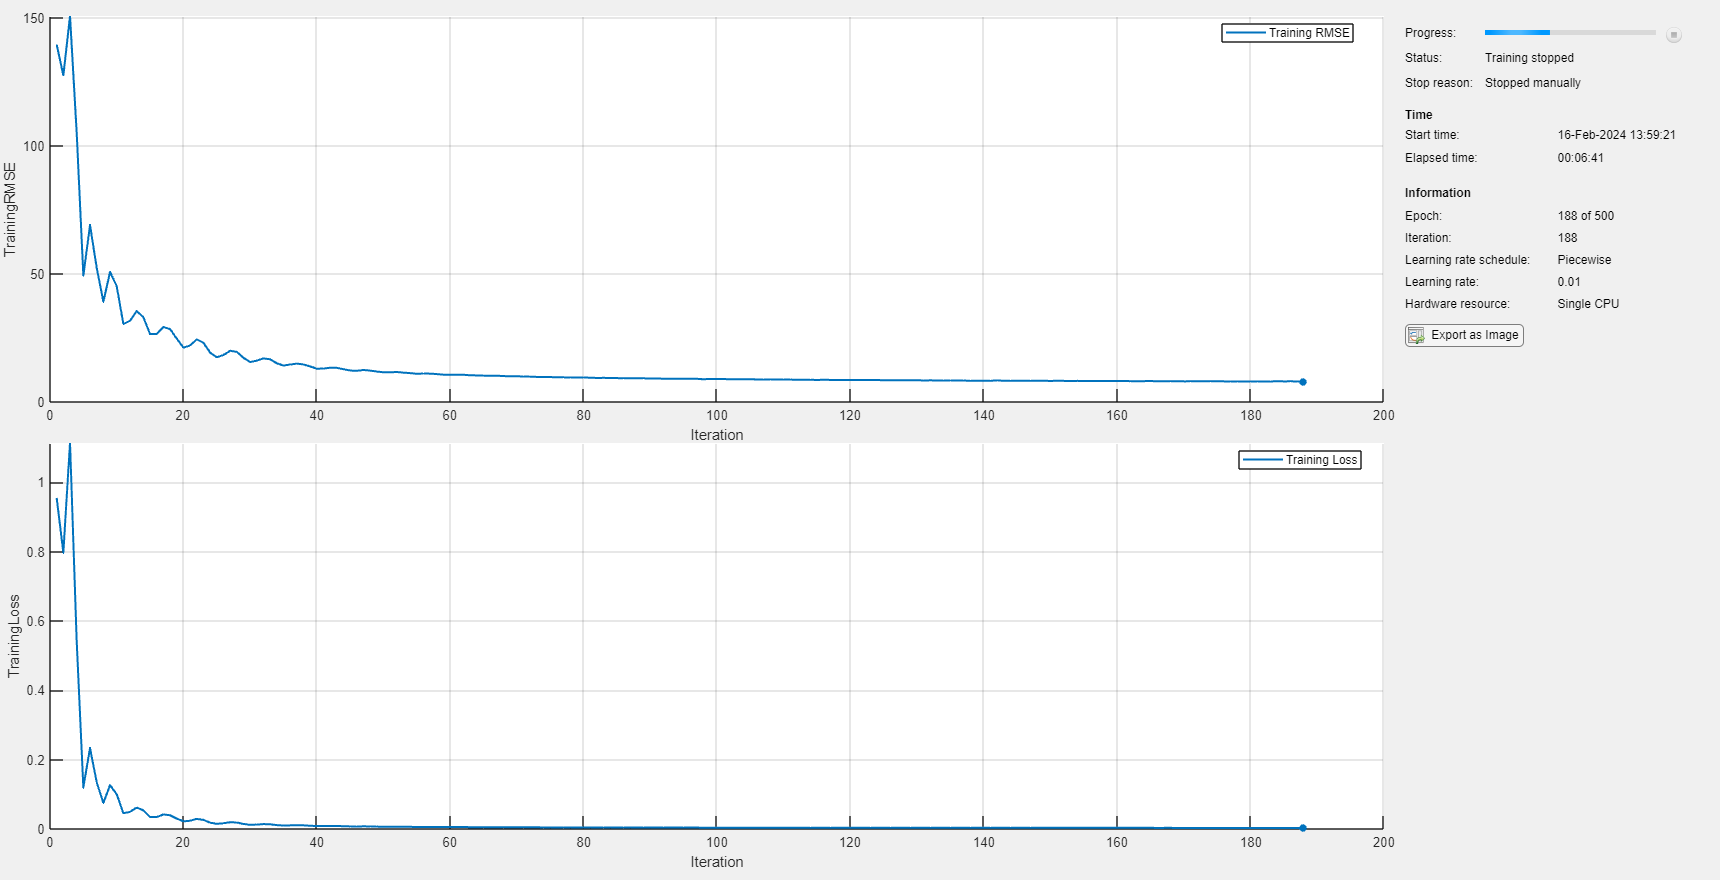

if train
    [net, ~] = trainnet(inputTrain,responseTrain,layers,'mse',opts);
    net = resetState(net);
    net_Path = fullfile(proj.RootFolder, root,"Models", "Components", "turboShaftEngineLSTM_ROM","turboshaft_ROM_v5.mat");
    save(net_Path,"net")
end

## Train with "trainNetwork"

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:04 |         2.59 |          3.4 |          0.0100 |
|      23 |          23 |       00:00:32 |         0.33 |      5.5e-02 |          0.0100 |
|========================================================================================|
Training finished: Stopped manually.


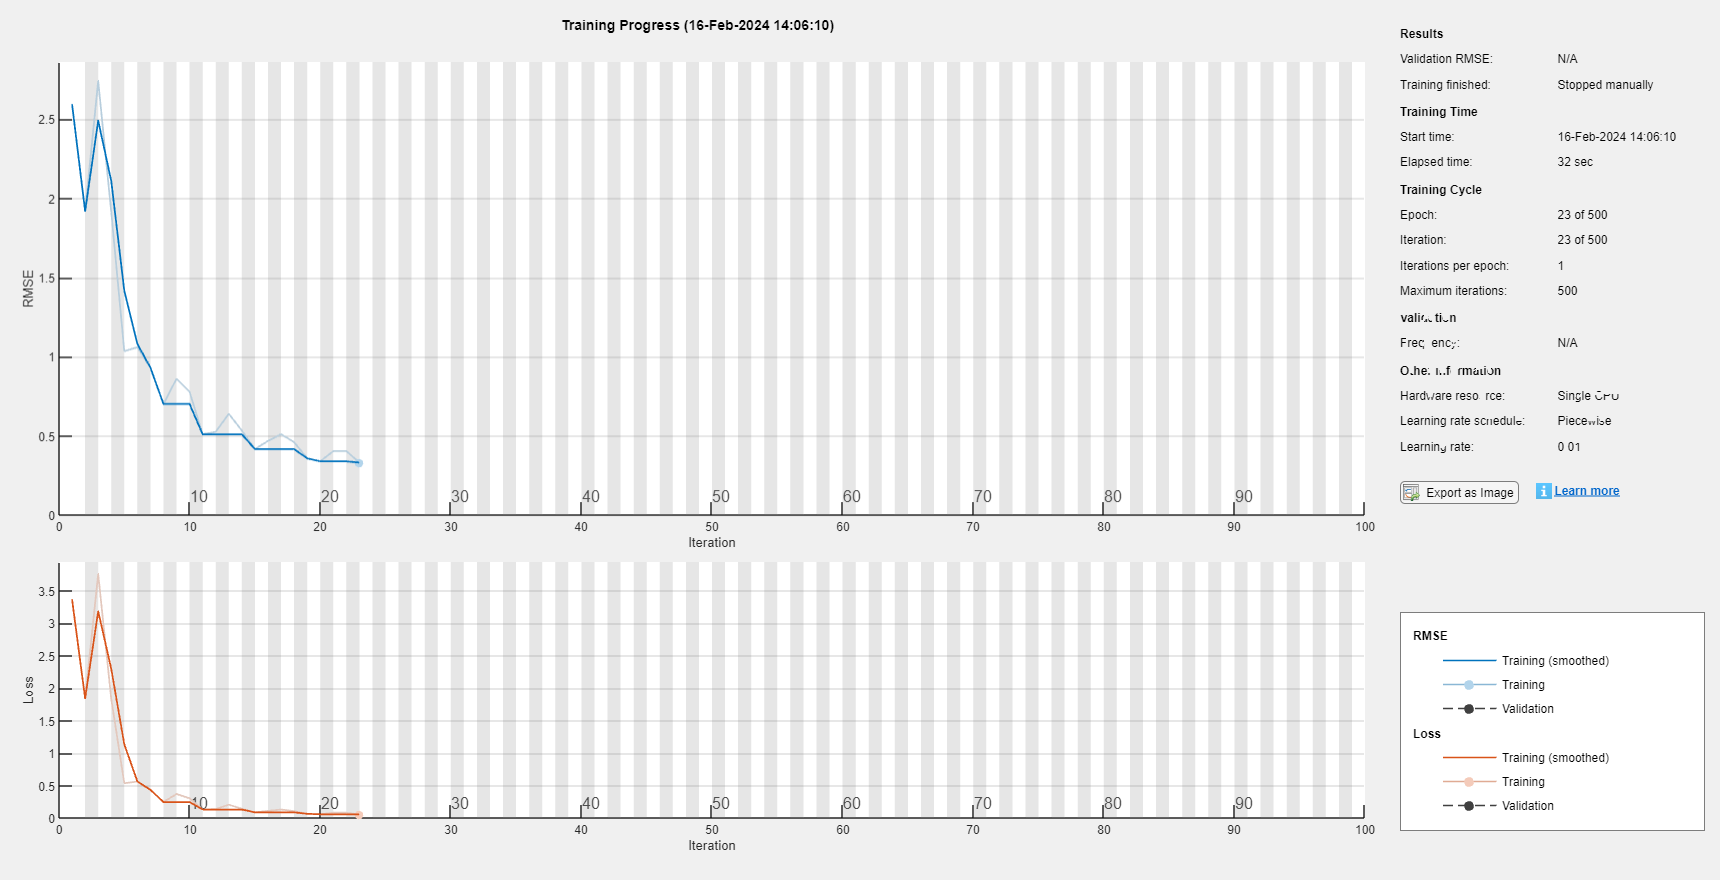

layers_TN = [
    sequenceInputLayer(numFeatures,"Name","input")
    lstmLayer(numHiddenUnits,"Name","lstm","OutputMode","sequence")
    dropoutLayer(dropoutProbability,"Name","drop")
    fullyConnectedLayer(numHiddenUnits,"Name","fc_1")
    fullyConnectedLayer(numResponses,"Name","fc_2")
    regressionLayer
    ];

opts_TN = trainingOptions("adam",...
    "ExecutionEnvironment","auto",...
    "InitialLearnRate",1e-2,...
    "MaxEpochs",500,...
    "Shuffle","every-epoch",... 
    "LearnRateSchedule","piecewise",...
    "LearnRateDropPeriod",200,...
    "LearnRateDropFactor",0.1,...
    "ValidationFrequency",10,...
    "Plots","training-progress");

for ix=1:numel(dataTrainNormComp)
    XTrainSep{ix} = inputTrain{ix}';
    TTrainSep{ix} = responseTrain{ix}';
end

if train
    [net_tN, traininfo] = trainNetwork(XTrainSep,TTrainSep,layers_TN,opts_TN);
    net_tN = resetState(net_tN);
    net_tN_Path = fullfile(proj.RootFolder, root,"Models", "Components", "turboShaftEngineLSTM_ROM","turboshaft_ROM_v6.mat");
    save(net_tN_Path,"net_tN")
end

## Integrate Trained LSTM Network in Simulink

You can use recurrent neural networks in simulink by using the "Stateful Predict" block 

engineMode = 'ROM';
set_param([modelName,'/Engine'],'LabelModeActivechoice', engineMode)
open_system(modelName)

# Evaluate results

Compare original and reduced model rregarding their resutls and simulation performance. This comparison is on a scenario that has not been included in the trainning.

mode = 'Custom';
set_param([modelName,'/HeatIn'],'LabelModeActivechoice', mode)
if train
    createInitializationDict
end

## Simulate the ROM

engineMode = 'ROM';
set_param([modelName,'/Engine'],'LabelModeActivechoice', engineMode)

Invalid Simulink object name: 'simpleHelicopter/Engine'.

Caused by:
    Error using turboshaftReduction
    The block diagram 'simpleHelicopter' is not loaded.

set_param([modelName,  '/Engine/ROM/Subsystem/Stateful Predict'], 'NetworkFilePath', net_tN_Path)
romSim = sim(modelName);
romRunID = Simulink.sdi.Run.getLatest;

## Simulate the Physical Model

Simulate the physical model with the same simulation scenario:

engineMode = 'PhysMod';
set_param([modelName,'/Engine'],'LabelModeActivechoice', engineMode)
refSim = sim(modelName);
refRunID = Simulink.sdi.Run.getLatest;

## Test in Simulation Data Inspector

Define the acceptable absolute and relative tolerances

relTol = 2.5e-2;
absTol = 6;

Launch comparison on the Simulation Data Inspector

Simulink.sdi.compareRuns(refRunID.id,romRunID.id,'RelTol',relTol,'AbsTol',absTol);
Simulink.sdi.view

## Performance comparison

Compare the Simulation Metadata containing information regarding the initialization, execution and total time of the simulation.

The timing info for the reference simulation

refSim.SimulationMetadata.TimingInfo;
ref.init = refSim.SimulationMetadata.TimingInfo.InitializationElapsedWallTime;
ref.execution = refSim.SimulationMetadata.TimingInfo.ExecutionElapsedWallTime;
ref.total = refSim.SimulationMetadata.TimingInfo.TotalElapsedWallTime;
baseline = [ref.init ref.execution ref.total];

The timing info for the ROM model

romSim.SimulationMetadata.TimingInfo;
rom.init = romSim.SimulationMetadata.TimingInfo.InitializationElapsedWallTime;
rom.execution = romSim.SimulationMetadata.TimingInfo.ExecutionElapsedWallTime;
rom.total = romSim.SimulationMetadata.TimingInfo.TotalElapsedWallTime;
reduced = [rom.init rom.execution rom.total];

Compare performance:

categories = categorical({'Initialization','Execution','Total'});
timereduction = (baseline-reduced)./baseline.*100;
bar(categories, timereduction, 0.3)
ylabel('Time reduction (%)')
grid('on')